# Drug Use Modelling Project

## Intro

**This SAR Model** has been developed to simulate drug addiction over time. We have a system of 3 differential equations that express the rates of change of 3 variables over time. Those are:

1. **S** - the susceptible to addiction;

2. **A** - the addicted.

3. **R** - the recovered from addiction.

## The Model

Here follow the 3 equations that govern the model dynamics:


$$\begin{array}{l}
\frac{\mathrm{dS}}{\mathrm{dt}}=-\beta \cdot \mathrm{S}\cdot \mathrm{I}+\delta \cdot \mathrm{R}\\
\frac{\mathrm{dI}}{\mathrm{dt}}=\beta \cdot \mathrm{S}\cdot \mathrm{I}-\gamma \cdot \mathrm{I}\\
\frac{\mathrm{dR}}{\mathrm{dt}}=\gamma \cdot \mathrm{I}-\delta \cdot 
\end{array}$$


## Model simulation

The following is a simulation of the model described above.

% Model parameters
b= 5*10^-9; % rate of addiction
g = 0.07; % rate of recovery (try also 0.12)
d = 0; % rate of relapse
N = 6*10^7; % Total population N = S + A + R
I0 = 10; % initial number of addicted
T = 300; % period of 300 days
dt = 1/4; % time interval of 6 hours (1/4 of a day)
D=6*10^-10; %death rate of population
fprintf('Value of parameter R0 is %.2f',N*b/g)

Value of parameter R0 is 4.29

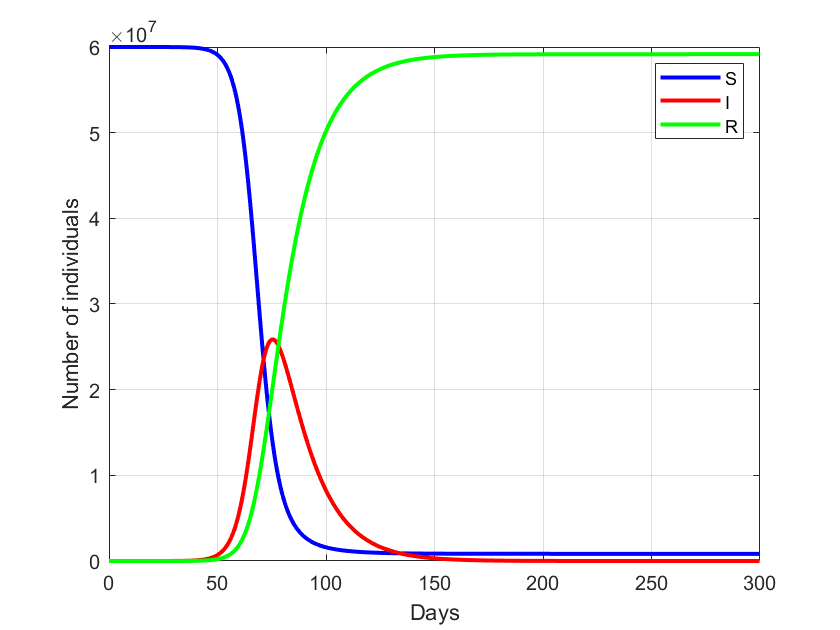

% Calculate the model
[S,A,R] = sar_model(b,g,d,D,N,I0,T,dt);
% Plots that display the epidemic outbreak
tt = 0:dt:T-dt;
% Curve
plot(tt,S,'b',tt,A,'r',tt,R,'g','LineWidth',2); grid on;
xlabel('Days'); ylabel('Number of individuals');
legend('S','I','R');

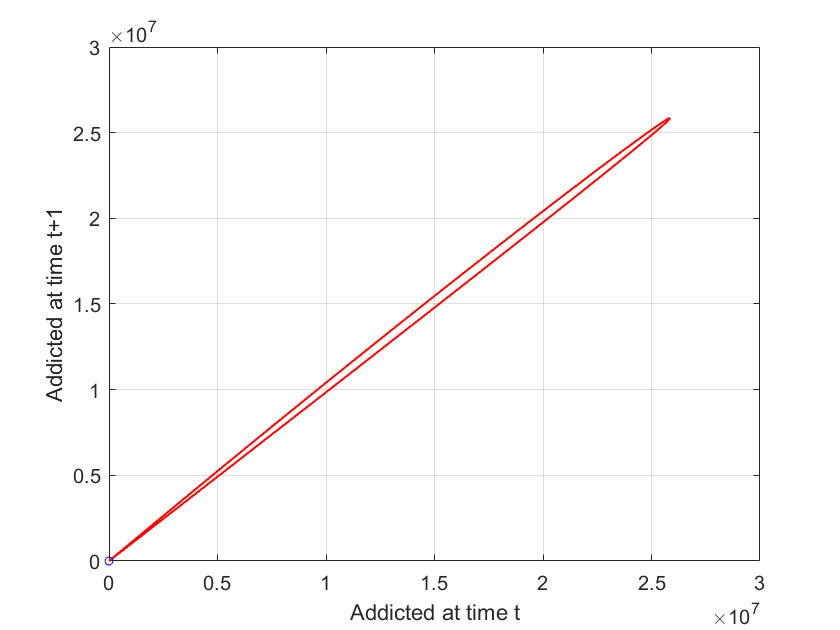

% Map
plot(A(1:(T/dt)-1),A(2:T/dt),"LineWidth",1,"Color",'r');
hold on; grid on;
plot(A(2),A(1),'ob','MarkerSize',4);
xlabel('Addicted at time t'); ylabel('Addicted at time t+1');
hold off;

## What if we consider Relapses?

In this case we consider people that relapse. Let’s assume that after 60 days from recovery (delta = 1/30), and display the new simulation.

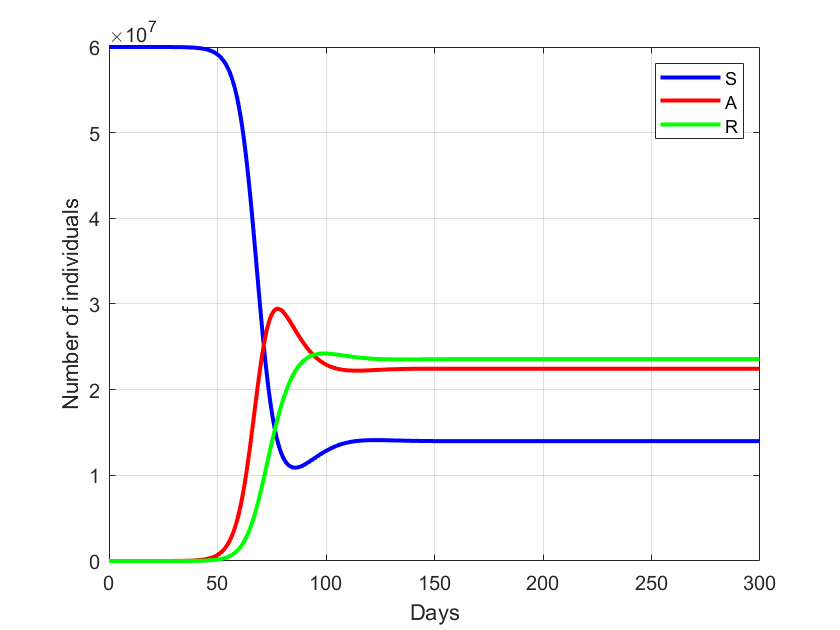

d = 1/15; % rate of relapse 
% Calculate the model
[S,A,R] = sar_model(b,g,d,D,N,I0,T,dt);
% Curve
plot(tt,S,'b',tt,A,'r',tt,R,'g','LineWidth',2); grid on;
xlabel('Days');ylabel('Number of individuals');
legend('S','A','R');

## Function that calculates the model evolution over a time period T.

function [S,A,R] = sar_model(b,g,d,D,N,I0,T,dt)
    % if delta = 0 we assume a model without relapse
    S = zeros(1,T/dt);
    S(1) = N;
    A = zeros(1,T/dt);
    A(1) = I0;
    R = zeros(1,T/dt);
    for tt = 1:(T/dt)-1
        % Equations of the model
        dS = (-b*A(tt)*S(tt) + d*R(tt)-D*S(tt)) * dt;
        dA = (b*A(tt)*S(tt) - g*A(tt)-D*A(tt)) * dt;
        dR = (g*A(tt) - d*R(tt)-D*R(tt)) * dt;
        S(tt+1) = S(tt) + dS;
        A(tt+1) = A(tt) + dA;
        R(tt+1) = R(tt) + dR;
    end
end